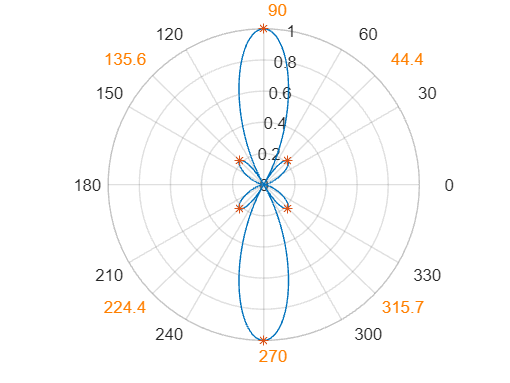

% Konst
lambda = 1;
k = 2 * pi / lambda;
theta = linspace(0, 2*pi + 0.001, 5000);

% Variabler
beta = 0;
d = lambda / 2;
N = 4;

% Array faktor
psi = k * d * cos(theta) + beta;
AF = abs(sin(N / 2 * psi) ./ (N / 2 * psi));

[pks, locs] = findpeaks(AF, theta);

figure;
polarplot(theta, AF);
hold on;
polarplot(locs, pks, '*');
hold off;

original_ticks = thetaticks;
new_ticks = round(rad2deg(locs), 1);
combined_ticks = unique([original_ticks, new_ticks]);
thetaticks(combined_ticks);

% Endre fargen på de nye theta-ticksene
ax = gca;
ax.ThetaTickLabel = cellstr(num2str(combined_ticks'));
for i = 1:length(new_ticks)
    idx = find(combined_ticks == new_ticks(i));
    ax.ThetaTickLabel{idx} = ['\color{orange}' ax.ThetaTickLabel{idx}];
end

hold off;